%% Simulation of linear system of monocopter with flaps
J = 3.2284E-6; % moment of inertia of the rotor
b = 3.5077E-6; % motor viscous friction constant 
K = 0.0274; % electromotive force constant, motor torque constant 
R = 4; % electric resistance 
L = 2.75E-6; % electric inductance  
s = tf('s');
servo = K/(s*((J*s+b)*(L*s+R)+K^2)); % includes the integral to positional angle alrd
H_servo = 1;
H_omega_dot_tf = 0.001; % lpf is needed and tuned here for indi, ndi is better only  
stf = servo/(1+(servo*H_servo));
%isstable(stf)
%pole(stf)
%omega_dot_tf = stf; % ndi
omega_dot_tf = stf/(1+(stf*H_omega_dot_tf)); % indi
%sys = feedback(stf,1); % implement feedback for tf which is servo to become servo/(1+(servo*H)

%% to simulate step input of a single servo angle
% t = 0:0.001:0.3;
% Config = RespConfig('Amplitude',5);
% step(omega_dot_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('Position, \theta (radians)')
% title('Response to a Step Reference')
%legend('Kp = 1',  'Kp = 11',  'Kp = 21')

%% to simulate disturbance step input
Jxx = 0.00099;
Jzz = 0.001;
% disturbance_torque_tf = ((1/J)*(1-(H_omega_dot_tf*omega_dot_tf)));
% t = 0:0.001:0.2;
% Config = RespConfig('Amplitude',5);
% step(disturbance_torque_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('omega_dot_tf')
% title('Response to a Step Disturbance')

%% to simulate step input to isolate precession portion and vertical rotation rate
hz = 5.6;
rps = hz * 2 * pi * -1;
H_precession = Jxx/(Jzz*rps) % dampener, precession inner loop

H_precession = -0.0281

%H_precession = 0;
precession_tf = omega_dot_tf/(1-(omega_dot_tf*H_precession)); % indi
% t = 0:0.001:0.3;
% Config = RespConfig('Amplitude',5);
% step(precession_tf, t, Config) % step function here is in the form of a servo angle 
% ylabel('radians/seconds')
% title('Response to a Step Reference')

%% find the lift force to hold alt 
g = 9.81;
cd = 0.023;
rho = 1.225;
radius = 0.61;
pitch = 1.0;
pitch = abs(pitch);
mass = 0.16;
cd = cd * pitch; % gradient for cd taken from naca 0006, pitch must be in deg
chord_length = 0.1;
drag_rotation = 1*(cd*rho*chord_length*(radius^3))/(6*mass);
com = 1/(-(g + drag_rotation));

H_disturbance_p = 1;
H_q = 1;
H_omega = 1;
H_a = 1;

kp_omega = 1;
kp_q = 1;
D = 0;

%needa isolate what is input 1,2,3, try and play around w the parameters above to find out their influence towards A 

%numerator = precession_tf*Jzz*rps*com*((s^2)+(s*kp_omega)+(D*kp_omega)+kp_q);
numerator = [precession_tf*Jzz*rps*com,precession_tf*Jzz*rps*com*kp_omega,precession_tf*Jzz*rps*com*((D*kp_omega)+kp_q)];
%denominator = (com((s^2)*((Jzz*rps)+(Jxx*precession_tf*H_disturbance_p))+(s*H_omega*precession_tf*kp_omega*Jzz*rps)+(precession_tf*kp_q*Jzz*rps*H_q))+(Jzz*rps*H_a*precession_tf));
denominator = [-1*com*Jxx*precession_tf*H_disturbance_p,Jzz*rps,H_omega*precession_tf*kp_omega*Jzz*rps,(com*precession_tf*kp_q*Jzz*rps*H_q) + (Jzz*rps*H_a*precession_tf)]

denominator =
 
  From input 1 to output:
                          1.202e-83 s^21 + 1.224e-76 s^20 + 5.341e-70 s^19 + 1.295e-63 s^18 + 1.883e-57 s^17 + 1.644e-51 s^16 + 7.974e-46 s^15 + 1.659e-40 s^14 + 6.869e-38 s^13 + 1.326e-35 s^12 + 1.579e-33 s^11 + 1.29e-31 s^10 + 7.577e-30 s^9 + 3.247e-28 s^8 + 1.006e-26 s^7 + 2.165e-25 s^6 + 2.946e-24 s^5 + 1.948e-23 s^4
  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
  3.86e-89 s^24 + 4.491e-82 s^23 + 2.287e-75 s^22 + 6.652e-69 s^21 + 1.21e-62 s^20 + 1.408e-56 s^19 + 1.024e-50 s^18 + 4.257e-45 s^17 + 7.751e-40 s^16 + 3.668e-37 s^15 + 8.261e-35 s^14 + 1.174e-32 s^13 + 1.174e-30 s^12 + 8.718e-29 s^11 + 4.928e-27 s^10 + 2.14e-25 s^9 + 7.104e-24 s^8 + 1

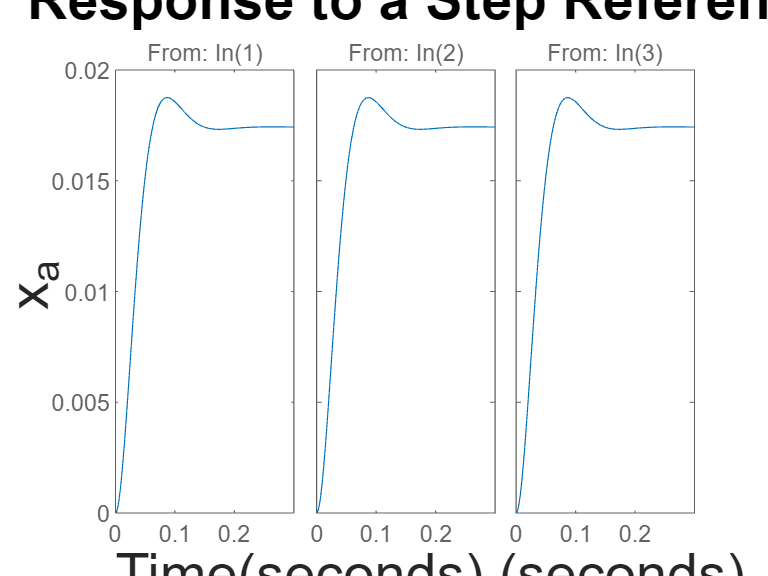

a_tf = tf(numerator,denominator);

t = 0:0.001:0.3;
Config = RespConfig('Amplitude',5);
step(a_tf, t, Config) % step function here is in the form of a servo angle 
ylabel('x_a','FontSize',24)
xlabel('Time(seconds)','FontSize',24)
title('Response to a Step Reference','FontSize',24)